## Wien Oscillator

Considr the Wien Oscillator depicted below:

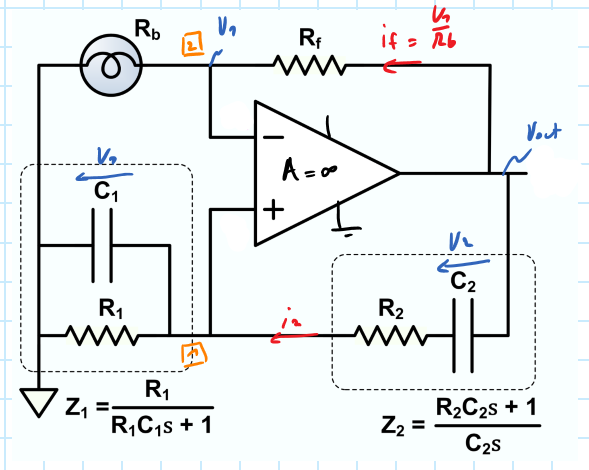

By applying KCL to the two orange nodes [1] and [2] we get the following:

% set up the physical equations and derive the system synamics in the form
% x_dot = A*x

syms v1 v2 v1dot v2dot c1 c2 r1 r2 rf rb s r c
%% simplification
c1 = c

$$c1 = c$$

c2 = c

$$c2 = c$$

r1 = r

$$r1 = r$$

r2 = r

$$r2 = r$$

%% /simplification

kcl1 = -c1*v1dot - v1/r1 + c2*v2dot == 0

$$kcl1 = c\,\mathrm{v2dot}-c\,\mathrm{v1dot}-\frac{v_{1}}{r}=0$$

kcl2 = -v1/rb+(v2+c2*r2*v2dot)/rf == 0

$$kcl2 = \frac{v_{2}+c\,r\,\mathrm{v2dot}}{\mathrm{rf}}-\frac{v_{1}}{\mathrm{rb}}=0$$

eqns=[kcl1,kcl2]

$$eqns = \left(\begin{array}{cc} c\,\mathrm{v2dot}-c\,\mathrm{v1dot}-\frac{v_{1}}{r}=0 & \frac{v_{2}+c\,r\,\mathrm{v2dot}}{\mathrm{rf}}-\frac{v_{1}}{\mathrm{rb}}=0 \end{array}\right)$$


S=solve(eqns,[v1dot,v2dot])

S = struct with fields:
    v1dot: [1×1 sym]
    v2dot: [1×1 sym]


S.v1dot=collect(S.v1dot,[v1 v2])

S = struct with fields:
    v1dot: [1×1 sym]
    v2dot: [1×1 sym]


S.v2dot=collect(S.v2dot,[v1 v2])

S = struct with fields:
    v1dot: [1×1 sym]
    v2dot: [1×1 sym]



%hint : the terms variable returned can be used to check to which term the
%coefficient corresponds
[v1dotcoeffs,terms]=coeffs(S.v1dot,[v1,v2])

$$v1dotcoeffs = \left(\begin{array}{cc} -\frac{\mathrm{rb}-\mathrm{rf}}{c\,r\,\mathrm{rb}} & -\frac{1}{c\,r} \end{array}\right)$$

$$terms = \left(\begin{array}{cc} v_{1} & v_{2} \end{array}\right)$$

disp(terms) %should display [v1,v2]

$$\left(\begin{array}{cc} v_{1} & v_{2} \end{array}\right)$$

[v2dotcoeffs,terms]=coeffs(S.v2dot,[v1,v2])

$$v2dotcoeffs = \left(\begin{array}{cc} \frac{\mathrm{rf}}{c\,r\,\mathrm{rb}} & -\frac{1}{c\,r} \end{array}\right)$$

$$terms = \left(\begin{array}{cc} v_{1} & v_{2} \end{array}\right)$$

disp(terms) %should display [v1,v2]

$$\left(\begin{array}{cc} v_{1} & v_{2} \end{array}\right)$$


%determine system matrix x_dot=A*x
A=[v1dotcoeffs(1),v1dotcoeffs(2);v2dotcoeffs(1),v2dotcoeffs(2)]

$$A = \left(\begin{array}{cc} -\frac{\mathrm{rb}-\mathrm{rf}}{c\,r\,\mathrm{rb}} & -\frac{1}{c\,r}\\ \frac{\mathrm{rf}}{c\,r\,\mathrm{rb}} & -\frac{1}{c\,r} \end{array}\right)$$

polepoly=det(A-sym(eye(2))*s)

$$polepoly = \frac{\mathrm{rb}+2\,c\,r\,\mathrm{rb}\,s-c\,r\,\mathrm{rf}\,s+c^{2}\,r^{2}\,\mathrm{rb}\,s^{2}}{c^{2}\,r^{2}\,\mathrm{rb}}$$

[num,den]=numden(polepoly)

$$num = \mathrm{rb}+2\,c\,r\,\mathrm{rb}\,s-c\,r\,\mathrm{rf}\,s+c^{2}\,r^{2}\,\mathrm{rb}\,s^{2}$$

$$den = c^{2}\,r^{2}\,\mathrm{rb}$$

num=collect(num,s)

$$num = \left(c^{2}\,r^{2}\,\mathrm{rb}\right)\,s^{2}+\left(2\,c\,r\,\mathrm{rb}-c\,r\,\mathrm{rf}\right)\,s+\mathrm{rb}$$

polepoly=num/den

$$polepoly = \frac{\left(c^{2}\,r^{2}\,\mathrm{rb}\right)\,s^{2}+\left(2\,c\,r\,\mathrm{rb}-c\,r\,\mathrm{rf}\right)\,s+\mathrm{rb}}{c^{2}\,r^{2}\,\mathrm{rb}}$$

The response of the system is given by:


$$X\left(s\right)={\left(A-sI_2 \right)}^{-1} x_0 =\frac{1}{\mathrm{det}\left(A-sI_2 \right)}\mathrm{Adj}\left(A-sI_2 \right)x_0$$


The poles of the system are therefore determined by $\mathrm{det}\left(A-sI_2 \right)$.


$$\mathrm{polepoly}(s) = \mathrm{det}\left(A-sI_2 \right) = \frac{\left(c^2\,r^2\,\mathrm{rb}\right)\,s^2+\left(2\,c\,r\,\mathrm{rb}-c\,r\,\mathrm{rf}\right)\,s+\mathrm{rb}}{c^2\,r^2\,\mathrm{rb}}$$


It can be seen that the system becomes oscillatory for $r_b =0\ldotp 5r_f$. The frequency of oscillation is given by $f_0 =\frac{1}{2\pi \sqrt{\mathrm{RC}}}$.

%Plot the root locus 
%

polepoly=subs(polepoly,c,0.1)

$$polepoly = \frac{100\,\left(\mathrm{rb}+s\,\left(\frac{r\,\mathrm{rb}}{5}-\frac{r\,\mathrm{rf}}{10}\right)+\frac{r^{2}\,\mathrm{rb}\,s^{2}}{100}\right)}{r^{2}\,\mathrm{rb}}$$

polepoly=subs(polepoly,r,1)

$$polepoly = \frac{100\,\left(\frac{\mathrm{rb}\,s^{2}}{100}+\left(\frac{\mathrm{rb}}{5}-\frac{\mathrm{rf}}{10}\right)\,s+\mathrm{rb}\right)}{\mathrm{rb}}$$

polepoly=subs(polepoly,rf,1)

$$polepoly = \frac{100\,\left(\frac{\mathrm{rb}\,s^{2}}{100}+\left(\frac{\mathrm{rb}}{5}-\frac{1}{10}\right)\,s+\mathrm{rb}\right)}{\mathrm{rb}}$$

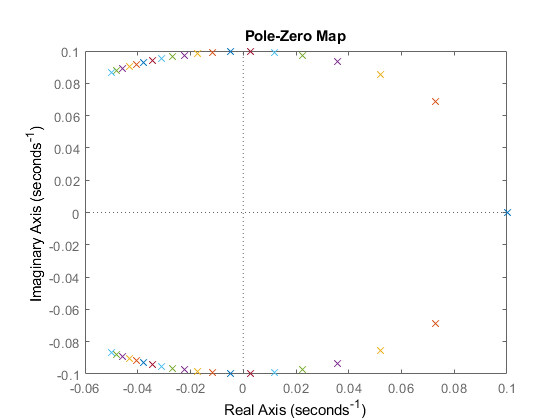


rbs=linspace(0.25,1,20);
for i=1:1:length(rbs)
    systf=subs(polepoly,rb,rbs(i));
    [n,d]=numden(systf);
    numcoeff=double(coeffs(n,s));
    dencoeff=double(coeffs(d,s));
    %hint : we want to plot the zeros of the polepolynomial as roots of the
    %dynamic system, therefore we need to set numcoeff as the denominator
    %in the following function call
    hold on;
    pzmap(tf(dencoeff,numcoeff));
end

The amplitude of the oscillation is stabilized by the resistor $r_b$. If too much current is running through $r_b$, the resistance will heat up leading to an increase of damping in the system. The net result will be a reduction of the real component of the system poles (e.g. the system will become more damped).


$$r_b =r_{b,0} +\alpha \left(T-T_0 \right)\;,\dot{T} ={c_{\mathrm{th},b} i}_b^2 r_b -\beta \left(T-T_0 \right)$$
